diff_deltaomega = 	1.0e+-3 *

    0.2037   -0.5409   -0.4777


diff_E =     0.0044    1.5078    1.1309
   -1.4956    0.0078   -0.3691
   -1.0956    0.4078    0.0309


W is not positive semi-definite.


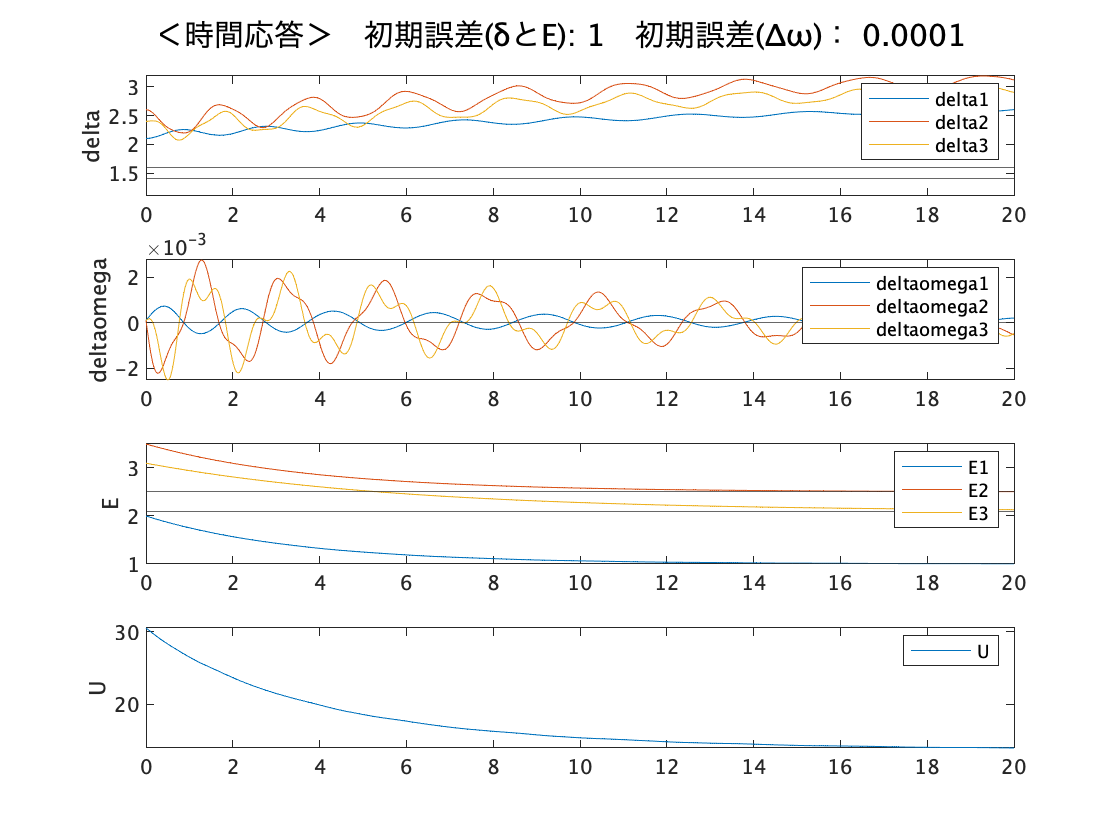

clear
tspan = [0 20];

%定常値を設定
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
steady_generator_state = [steady_delta; steady_deltaomega; steady_E];

plot_generator_state_wrap = @(cnt) plot_generator_state(cnt,tspan,steady_generator_state);

for rng = 1
    figure;
    t_U = plot_generator_state_wrap(rng);
    sgtitle(['＜時間応答＞　初期誤差(δとE): ',num2str(rng), '　初期誤差(Δω)： ',num2str(rng*0.0001)]);
end

figure;
f = fit(t_U(:,1),t_U(:,2),'poly4');
syms x f1(x) diff2_f1(x)
f1(x) = f.p1*x^4 + f.p2*x^3 + f.p3*x^2 + f.p4*x + f.p5;
diff2_f1(x) = diff(f1,2);
diff2_f1(1:10)  %任意のxで W(x)>=0 

$$ans = \left(\begin{array}{cccccccccc} \frac{3215330908068351671}{4611686018427387904} & \frac{680437032370489799}{1152921504606846976} & \frac{2269878731687294255}{4611686018427387904} & \frac{116232669667772303}{288230376151711744} & \frac{1491280078473146975}{4611686018427387904} & \frac{291137705763416159}{1152921504606846976} & \frac{879534948425909831}{4611686018427387904} & \frac{9941132102966915}{72057594037927936} & \frac{434643341545582823}{4611686018427387904} & \frac{68691902323252655}{1152921504606846976} \end{array}\right)$$

F = solve(diff2_f1 == 0, x)  %かつ、これが複素数なら蓄積関数WはRealな解を持たなくて、半正定関数

$$F = \left(\begin{array}{c} \frac{92692141628997296}{6952230131954589}-\frac{16\,\sqrt{390264521765047527869321495579}\,\mathrm{i}}{6952230131954589}\\ \frac{92692141628997296}{6952230131954589}+\frac{16\,\sqrt{390264521765047527869321495579}\,\mathrm{i}}{6952230131954589} \end{array}\right)$$

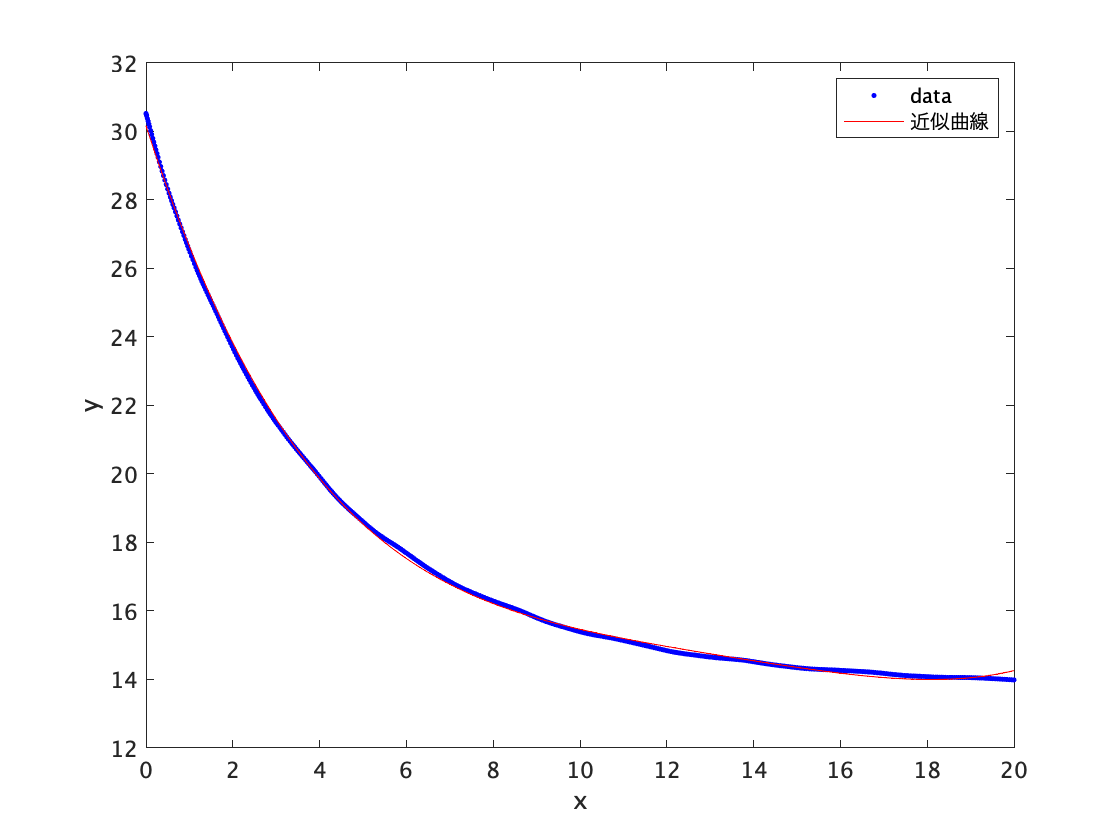


plot(f,t_U(:,1),t_U(:,2))